% Your matrix
NROW = length(posDots);
NG = 6; % The number of groups

% Generate an index that assigns each row to one of the groups
groupIndex = randi(NG,NROW,1);
% Assign the rows to their own matrix (in a cell array)
Mg = cell(NG,1);
for nn = 1:NG
    Mg{nn} = posDots(groupIndex==nn,:);
end


% Your matrix
numRows = length(posDots);
numGroups = numIntensities; % The number of groups


% Generate an index that assigns each row to one of the groups
groupIndex = randi(numGroups,numRows,1);

mu = [3, 3; 6,7];
sigma = []

for i=1:N
    for j=i:N
        X_i = posDots(i, :);
        X_j = posDots(j, :);

        spatial_proximity = (X_i(1) - mu(1))^2 + (X_i(2) - mu(2))^2;
        distance = sqrt(spatial_proximity);

        if distance <= r
            groupIndex(i) = id;
        end


    end
end


mus = [1,1;
      4,4;
      7,7;
      10,10];
sigma = [1.5];


intensityDots = zeros(numDots,numDots);

mu = mus(1,:);
row = mu(1); col = mu(2);

r = round(sigma);
x = max(col - r, 1):1:min(col + r, numDots);
y = max(row - r, 1):1:min(row + r, numDots);

[X, Y] = meshgrid(x, y);

% Compute distances from the mu
R = sqrt((X - col).^2 + (Y - row).^2)

R =          0    1.0000    2.0000
    1.0000    1.4142    2.2361
    2.0000    2.2361    2.8284


% Find the dots which are in the range
mask = R <= radius;

% Array of dot positions in the range 
cluster = cat(2, X(mask), Y(mask));

intensityDots(cluster(:,1), cluster(:,2)) = intensities(i);


mu = [3, 3; 6,7];
% Concatanate covariances on third dimension
sigma = cat(3,[.5 .5],[1 1]);
% Create equal proportion mixture
gm = gmdistribution(mu,sigma);
% Generate random clusters with the provided means and sigmas
[Y,compIdx] = random(gm,100);
numGroups = 6;

% Find the range
ranges = cell(numGroups,2);
for i=1:numGroups
    ranges{i,1} = min(Y(compIdx == i));
    ranges{i,2} = max(Y(compIdx == i));
end

gmFit = fitgmdist(posDots, 6);

groupIndex = cluster(gmFit, posDots);


% Your matrix
numRows = length(posDots);
numGroups = numIntensities; % The number of groups

%% Voronoi Diagram
cx = randi([0,10],1,numGroups);
cy = randi([0,10],1,numGroups);

groupIndex = NaN(1,length(posDots));

for i=1:length(posDots)
    x = posDots(i,1);
    y = posDots(i,2);

    minD = 100; % minimal distanced center
    c = 1; % center

    for k=1:numGroups
        if (x - cx(k))^2 + (y - cy(k))^2 <=minD
            minD = (x - cx(k))^2 + (y - cy(k))^2;
            c = k;
        end
    end

    groupIndex(i) = c;
end

% Assign dots into the groups
clusters = cell(numGroups,1);
for i=1:numGroups
    clusters{i} = posDots(groupIndex == i,:); 
end


% Initialize the matrix
intensityDots = zeros(numDots, numDots);
for j=1:numGroups
    cluster = clusters{j};
    lenCluster = length(cluster);

    for k=1:lenCluster
        intensityDots(cluster(k,1), cluster(k,2)) = intensities(j);
    end
    
end


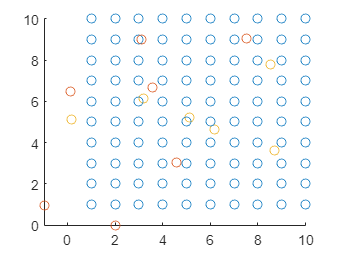

numGroups = numIntensities; % The number of groups

%% Voronoi Diagram
% cx = randi([0,10],1,numGroups);
% cy = randi([0,10],1,numGroups);

cx = [2,5,8,2,5,8];
cy = [3,3,3,7,7,7];
stdx = normrnd(0,1,[1,numGroups]);
stdy = normrnd(0,1,[1,numGroups]);

cx = cx + stdx;
cy = cy + stdy;

groupIndex = NaN(1,length(posDots));

for i=1:length(posDots)
    x = posDots(i,1);
    y = posDots(i,2);

    minD = 100; % minimal distanced center
    c = 1; % center

    for k=1:numGroups
        if (x - cx(k))^2 + (y - cy(k))^2 <=minD
            minD = (x - cx(k))^2 + (y - cy(k))^2;
            c = k;
        end
    end

    groupIndex(i) = c;
end

scatter(posDots(:,1), posDots(:,2));
scatter(cx, cy);


% Assign dots into the groups
clusters = cell(numGroups,1);
for i=1:numGroups
    clusters{i} = posDots(groupIndex == i,:); 
end


% Initialize the matrix
intensityDots = zeros(numDots, numDots);
for j=1:numGroups
    cluster = clusters{j};
    lenCluster = size(cluster,1);

    for k=1:lenCluster
        intensityDots(cluster(k,1), cluster(k,2)) = intensities(j);
    end
end
